# Analysis

pilot data from the 'counterfactual stimuli' experiment.

## Load data

%data_struct = loadData; %load actual participant data
data_struct = loadSimulatedData('Scalar');
full_subj_list = data_struct.keys;

## Select subjects for analysis

%subj_list = full_subj_list(1:10) %random walk; difficult; faces&houses
%subj_list = full_subj_list(11:24) %random walk; easy; faces
%subj_list = full_subj_list(25:29) %linear; easy
%subj_list = full_subj_list(30:34) %linear; difficult
%subj_list = full_subj_list(35) %ME doing difficult linear
subj_list = full_subj_list %take all subjects (e.g. final or simulated data)

subj_list = 1×100 cell array
    {'subj_100_ScalarModel'}    {'subj_10_ScalarModel'}    {'subj_11_ScalarModel'}    {'subj_12_ScalarModel'}    {'subj_13_ScalarModel'}    {'subj_14_ScalarModel'}    {'subj_15_ScalarModel'}    {'subj_16_ScalarModel'}    {'subj_17_ScalarModel'}    {'subj_18_ScalarModel'}    {'subj_19_ScalarModel'}    {'subj_1_ScalarModel'}    {'subj_20_ScalarModel'}    {'subj_21_ScalarModel'}    {'subj_22_ScalarModel'}    {'subj_23_ScalarModel'}    {'subj_24_ScalarModel'}    {'subj_25_ScalarModel'}    {'subj_26_ScalarModel'}    {'subj_27_ScalarModel'}    {'subj_28_ScalarModel'}    {'subj_29_ScalarModel'}    {'subj_2_ScalarModel'}    {'subj_30_ScalarModel'}    {'subj_31_ScalarModel'}    {'subj_32_ScalarModel'}    {'subj_33_ScalarModel'}    {'subj_34_ScalarModel'}    {'subj_35_ScalarModel'}    {'subj_36_ScalarModel'}    {'subj_37_ScalarModel'}    {'subj_38_ScalarModel'}    {'subj_39_ScalarModel'}    {'subj_3_ScalarModel'}    {'subj_40_ScalarModel'}    {'subj_41_ScalarModel'} 

## Initialize

addpath('~/Documents/software/cbrewer') %for color
[cb] = cbrewer('qual','Set1',10,'pchip');
addpath('~/Documents/software/raincloud_plots') %for rainclouds
addpath('~/Documents/software/mseb'); %for nice shaded errors
lineProps.width=1; lineProps.col = {cb(1,:), cb(4,:)};
linePropsDiff.width=1; linePropsDiff.col = {'k'}; linePropsDiff.style = '-';

## Accuracy

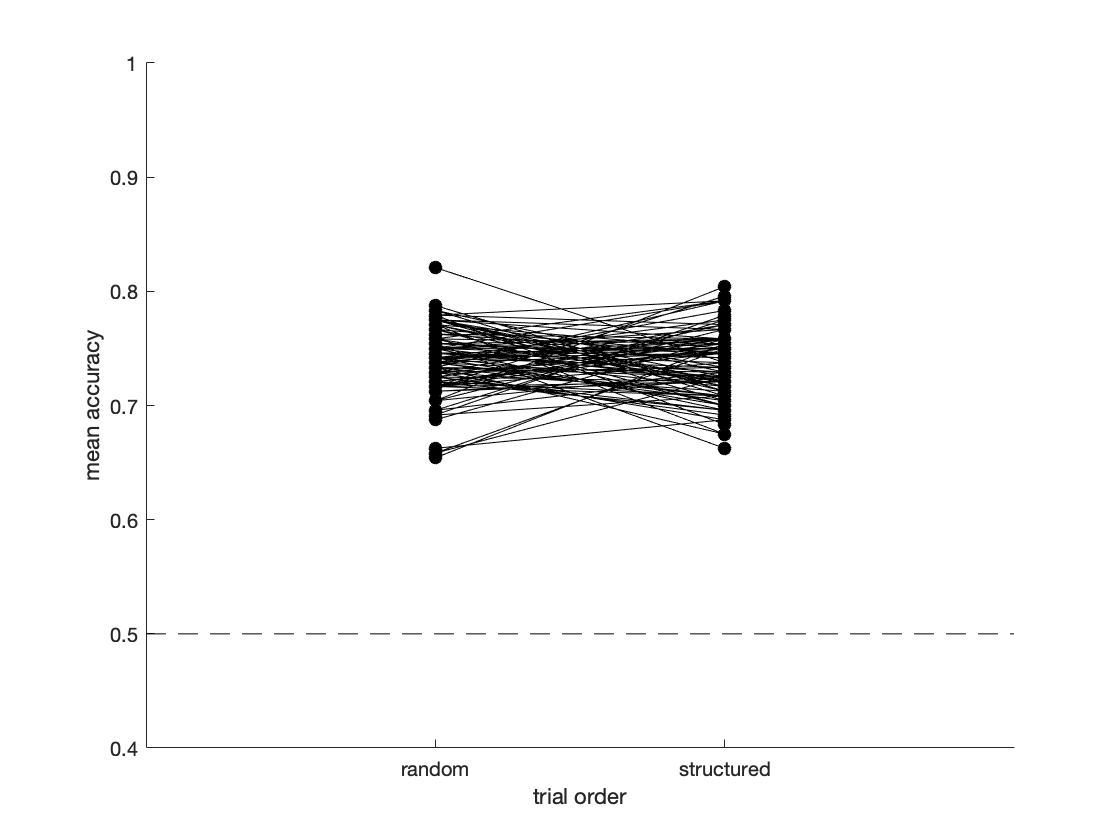

[rand_acc,struct_acc] = deal(nan(numel(subj_list),1));
for i_s = 1:numel(subj_list)
    subj = subj_list{i_s};
    rand_acc(i_s) = nanmean(data_struct(subj).RandomCorrect);
    struct_acc(i_s) = nanmean(data_struct(subj).StructCorrect);
end

figure; hold on;
plot([rand_acc';struct_acc'],'-ok','MarkerFaceColor','k');
ylabel('mean accuracy');
xlim([0,3]); xlabel('trial order');
ylim([0.4,1]);
plot([0,3],[0.5,0.5],'k--')
set(gca,'xtick',[1:2],'xticklabel',{'random','structured'});

%useful values
rand_acc_mean = nanmean(rand_acc);
struct_acc_mean = nanmean(struct_acc);
% sprintf('Mean Random Accuracy = %.2f, Mean Structured Accuracy = %.2f',rand_acc_mean,struct_acc_mean)
%check significance
[h,p,ci,stats] = ttest(rand_acc-struct_acc);
sprintf(['Significance test: difference in accuracy between structured and ' ...
    'random conditions: t(%d)=%.2f, p=%.3f'],stats.df,stats.tstat,p)

ans = 'Significance test: difference in accuracy between structured and random conditions: t(99)=0.63, p=0.529'

## Accuracy

Contrasting mean accuracy and d' for the two tasks.

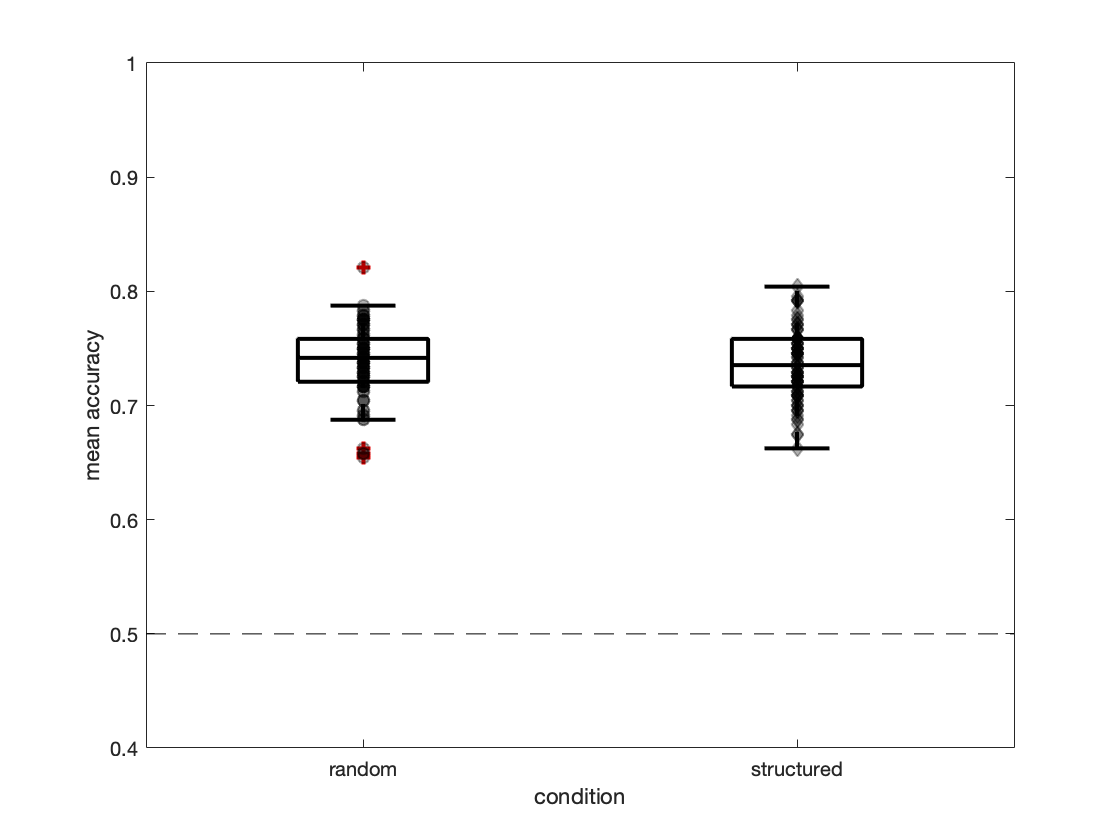

meanAccRand = [];
meanAccStruct = [];
mean_dprimeRand = [];
mean_dprimeStruct = [];
meanAUROCRand = [];
meanAUROCStruct = [];

for s = 1:length(subj_list)
    
    subject = data_struct(subj_list{s});
    
    AccRand = subject.RandomCorrect;
    AccStruct = subject.StructCorrect;
    meanAccRand(s) = nanmean(AccRand);
    meanAccStruct(s) = nanmean(AccStruct);
    
   
%     dprimeRand = norminv(nanmean(subject.RandomResp(subject.RandomSignal == 1))) - ...
%         norminv(nanmean(subject.RandomResp(subject.RandomSignal == 0)));
%     
%     dprimeStruct = norminv(nanmean(subject.StructResp(subject.StructSignal == 1))) - ...
%         norminv(nanmean(subject.StructResp(subject.StructSignal == 0)));
%     
%     AUROCRand = extractAUROC(subject.RandomSignal,subject.RandomResp,subject.RandomConf);
%     AUROCStruct = extractAUROC(subject.StructSignal,subject.StructResp,subject.StructConf);
%     
%     mean_dprimeRand(s) = dprimeRand;
%     mean_dprimeStruct(s) = dprimeStruct;
%     
%     meanAUROCRand(s) = AUROCRand;
%     meanAUROCStruct(s) = AUROCStruct;
    
end
noise1 = normrnd(0,0.05,1,35);
noise2 = normrnd(0,0.05,1,35);
figure; hold on;
h=boxplot([meanAccRand;meanAccStruct]','Colors','k');
set(h,{'linew'},{2})
% plot([ones(1,35)+noise1; 2*ones(1,35)+noise2],[meanAccDis;meanAccDet],'color',[0.5,0.5,0.5]);
scatter(2*ones(length(subj_list),1)',meanAccStruct,[],'d','MarkerEdgeColor','k','MarkerFaceColor',...
    [0,0,0],'LineWidth',1, 'MarkerEdgeAlpha',0.3,'MarkerFaceAlpha',0.3);
scatter(ones(length(subj_list),1),meanAccRand,[],'MarkerEdgeColor','k','MarkerFaceColor',...
    [0,0,0],'LineWidth',1,'MarkerEdgeAlpha',0.3,'MarkerFaceAlpha',0.3);
ylabel('mean accuracy');
xlim([0.5,2.5]); xlabel('condition');
ylim([0.4,1]);
plot([0.5,2.5],[0.5,0.5],'k--')
set(gca,'xtick',[1:2],'xticklabel',{'random','structured'})
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/meanAccuracy','-dpng','-r600');

%print('figures/accuracy_300dpi','-dpng','-r300');
% figure; hold on;
% plot([mean_dprimeStruct;mean_dprimeRand],'k');
% scatter(ones(length(subj_list),1),mean_dprimeStruct,[],'MarkerEdgeColor','k','MarkerFaceColor',[0,0,0],'LineWidth',1);
% scatter(2*ones(length(subj_list),1),mean_dprimeRand,[],'MarkerEdgeColor','k','MarkerFaceColor',[0,0,0],'LineWidth',1);
% ylabel('mean d''');
% xlim([0,3]); xlabel('task');
% set(gca,'xtick',[1:2],'xticklabel',{'structured','random'})

## Mean reaction times and confidence for the four conditions

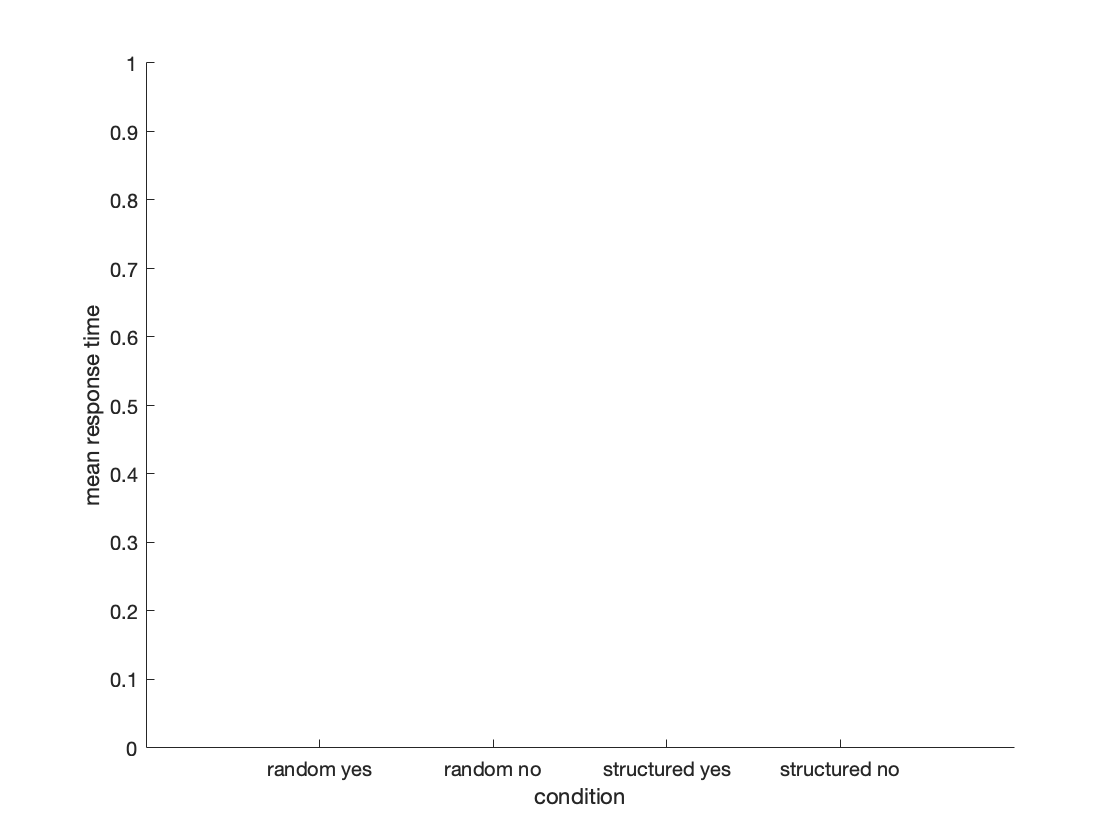

meanRT_rand_yes = [];
meanRT_rand_no = [];
meanRT_struct_yes = [];
meanRT_struct_no = [];
meanRT_correct = [];
meanRT_incorrect = [];
meanConf_rand_yes = [];
meanConf_rand_no = [];
meanConf_struct_yes = [];
meanConf_struct_no = [];

for s = 1:length(subj_list)
    
    subject = data_struct(subj_list{s});
    
    RT_rand_yes = subject.RandomRT(subject.RandomResp==1);
    RT_rand_no = subject.RandomRT(subject.RandomResp==0);
    RT_struct_yes = subject.StructRT(subject.StructResp==1);
    RT_struct_no = subject.StructRT(subject.StructResp==0);
    
    meanRT_rand_yes(s) = nanmean(RT_rand_yes);
    meanRT_rand_no(s) = nanmean(RT_rand_no);
    meanRT_struct_yes(s) = nanmean(RT_struct_yes);
    meanRT_struct_no(s) = nanmean(RT_struct_no);
    
    RT_correct = [subject.RandomRT(subject.RandomCorrect ==1); ...
        subject.StructRT(subject.StructCorrect ==1)];
    RT_incorrect = [subject.RandomRT(subject.RandomCorrect ==0); ...
        subject.StructRT(subject.StructCorrect ==0)];
    
    meanRT_correct(s) = nanmean(RT_correct);
    meanRT_incorrect(s) = nanmean(RT_incorrect);
    
    conf_rand_yes = subject.RandomConf(subject.RandomResp==1);
    conf_rand_no = subject.RandomConf(subject.RandomResp==0);
    conf_struct_yes = subject.StructConf(subject.StructResp==1);
    conf_struct_no = subject.StructConf(subject.StructResp==0);
    
    meanConf_rand_yes(s) = nanmean(conf_rand_yes);
    meanConf_rand_no(s) = nanmean(conf_rand_no);
    meanConf_struct_yes(s) = nanmean(conf_struct_yes);
    meanConf_struct_no(s) = nanmean(conf_struct_no);
    
end

figure; hold on;
plot([meanRT_rand_yes;meanRT_rand_no;meanRT_struct_yes;meanRT_struct_no],'k');
scatter(ones(length(subj_list),1),meanRT_rand_yes,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(2*ones(length(subj_list),1),meanRT_rand_no,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
scatter(3*ones(length(subj_list),1),meanRT_struct_yes,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(4*ones(length(subj_list),1),meanRT_struct_no,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
ylabel('mean response time');
xlim([0,5]); xlabel('condition');
set(gca,'xtick',[1:4],'xticklabel',{'random yes','random no','structured yes','structured no'})

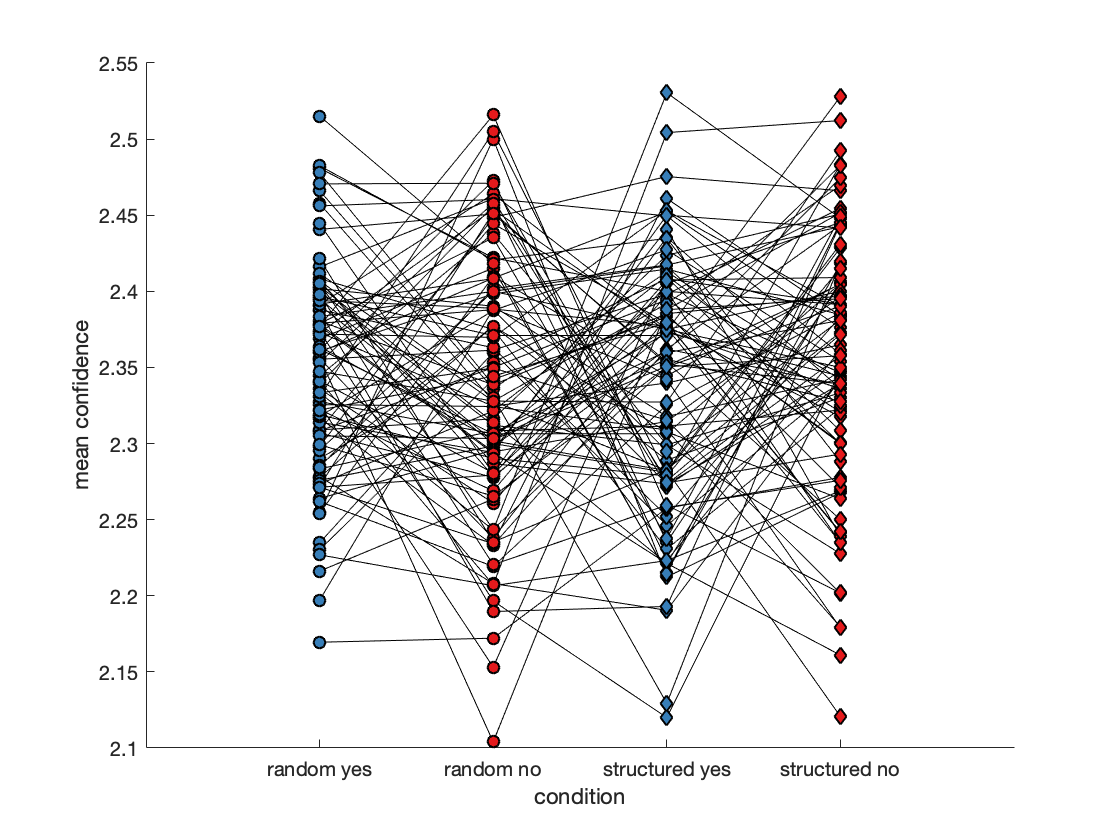

fig = gcf;
fig.PaperUnits = 'inches';
%print('figures/meanRT','-dpng','-r600');

figure; hold on;
plot([meanConf_rand_yes;meanConf_rand_no;meanConf_struct_yes;meanConf_struct_no],'k');
scatter(ones(length(subj_list),1),meanConf_rand_yes,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(2*ones(length(subj_list),1),meanConf_rand_no,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
scatter(3*ones(length(subj_list),1),meanConf_struct_yes,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(4*ones(length(subj_list),1),meanConf_struct_no,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
ylabel('mean confidence');
xlim([0,5]); xlabel('condition');
set(gca,'xtick',[1:4],'xticklabel',{'random yes','random no','structured yes','structured no'})
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/meanConfidence','-dpng','-r600');

## Confidence

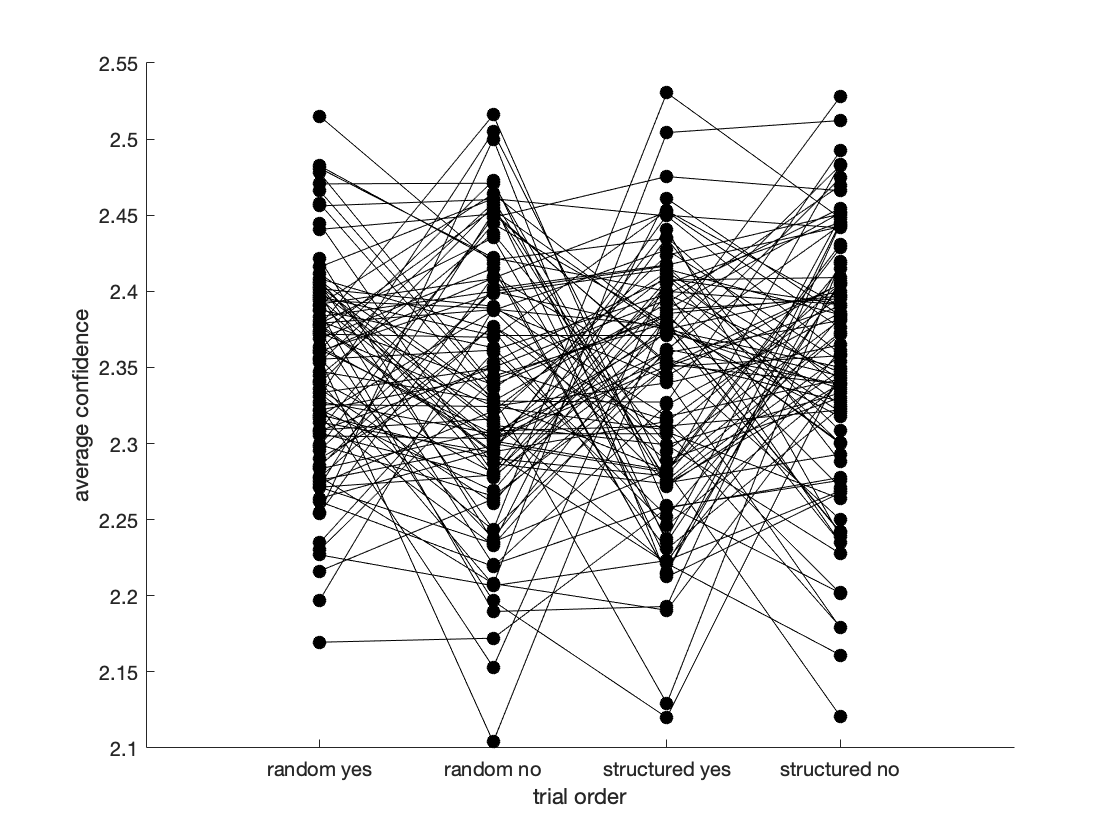

[rand_yes_conf,rand_no_conf,struct_yes_conf, struct_no_conf] = deal(nan(numel(subj_list),1));
for i_s = 1:numel(subj_list)
    subj = subj_list{i_s};
    rand_yes_conf(i_s) = nanmean(data_struct(subj).RandomConf(data_struct(subj).RandomResp==1));
    rand_no_conf(i_s) = nanmean(data_struct(subj).RandomConf(data_struct(subj).RandomResp==0));
    struct_yes_conf(i_s) = nanmean(data_struct(subj).StructConf(data_struct(subj).StructResp==1));
    struct_no_conf(i_s) = nanmean(data_struct(subj).StructConf(data_struct(subj).StructResp==0));
end

figure; hold on;
plot([rand_yes_conf';rand_no_conf';struct_yes_conf';struct_no_conf'],'-ok','MarkerFaceColor','k');
ylabel('average confidence');
xlim([0,5]); xlabel('trial order');
set(gca,'xtick',[1:4],'xticklabel',{'random yes','random no', 'structured yes','structured no'});

%useful values
[rand_yes_conf_mean,rand_no_conf_mean,struct_yes_conf_mean, struct_no_conf_mean] = ...
    deal(nanmean(rand_yes_conf),nanmean(rand_no_conf),nanmean(struct_yes_conf), nanmean(struct_no_conf))

rand_yes_conf_mean = 2.3487

rand_no_conf_mean = 2.3382

struct_yes_conf_mean = 2.3389

struct_no_conf_mean = 2.3562

%check significance
[h,p,ci,stats] = ttest(rand_no_conf-struct_no_conf);
sprintf(['Significance test: difference in visibility-confidence correlations between structured and ' ...
    'random conditions in no responses: t(%d)=%.2f, p=%.3f'],stats.df,stats.tstat,p)

ans = 'Significance test: difference in visibility-confidence correlations between structured and random conditions in no responses: t(99)=-1.51, p=0.135'

[h,p,ci,stats] = ttest(rand_yes_conf-struct_yes_conf);
sprintf(['Significance test: difference in visibility-confidence correlations between structured and ' ...
    'random conditions in yes responses: t(%d)=%.2f, p=%.3f'],stats.df,stats.tstat,p)

ans = 'Significance test: difference in visibility-confidence correlations between structured and random conditions in yes responses: t(99)=0.89, p=0.376'

## Visibility-confidence correlation

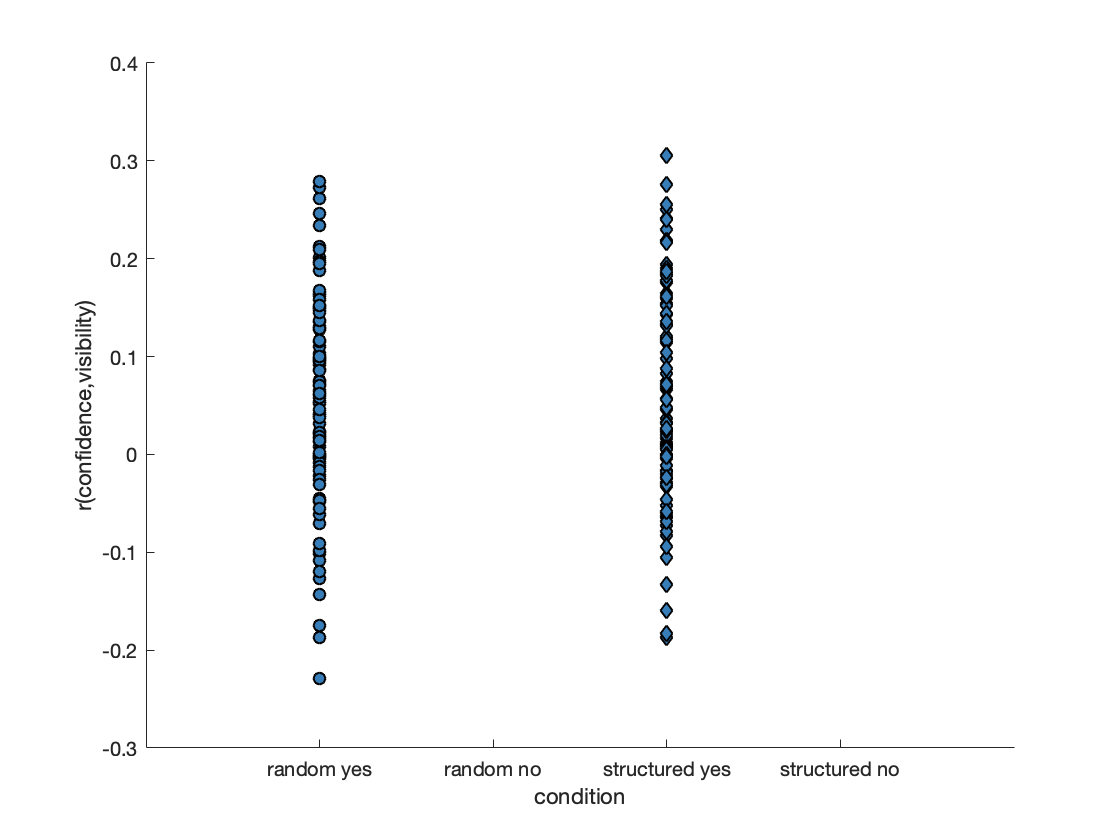

[rand_yes_VCcorr,struct_yes_VCcorr, rand_no_VCcorr, struct_no_VCcorr] = deal(nan(size(subj_list)));

for i_s = 1:numel(subj_list)
    
    subj = subj_list{i_s};
    
    demeaned_random_confidence = data_struct(subj).RandomDemeanConf;
    demeaned_struct_confidence = data_struct(subj).StructDemeanConf;
    demeaned_random_vis = data_struct(subj).RandomDemeanVisibility;
    demeaned_struct_vis = data_struct(subj).StructDemeanVisibility;
    
    rand_yes_VCcorr(i_s) = nancorr(demeaned_random_vis(data_struct(subj).RandomResp==1 & data_struct(subj).RandomCorrect==1),...
        demeaned_random_confidence(data_struct(subj).RandomResp==1 & data_struct(subj).RandomCorrect==1));
    struct_yes_VCcorr(i_s) = nancorr(demeaned_struct_vis(data_struct(subj).StructResp==1 & data_struct(subj).StructCorrect==1),...
        demeaned_struct_confidence(data_struct(subj).StructResp==1 & data_struct(subj).StructCorrect==1));
    
    rand_no_VCcorr(i_s) = nancorr(demeaned_random_vis(data_struct(subj).RandomResp==0 & data_struct(subj).RandomCorrect==1),...
        demeaned_random_confidence(data_struct(subj).RandomResp==0 & data_struct(subj).RandomCorrect==1));
    struct_no_VCcorr(i_s) = nancorr(demeaned_struct_vis(data_struct(subj).StructResp==0 & data_struct(subj).StructCorrect==1),...
        demeaned_struct_confidence(data_struct(subj).StructResp==0 & data_struct(subj).StructCorrect==1));
    
end
%{
figure; hold on;
plot([rand_yes_VCcorr;rand_no_VCcorr;struct_yes_VCcorr;struct_no_VCcorr],'-ok','MarkerFaceColor','k');
ylabel('r(confidence,visibility)');
xlim([0,5]); xlabel('trial order');
set(gca,'xtick',[1:4],'xticklabel',{'random yes','random no', 'structured yes','structured no'});
%}

figure; hold on;
plot([rand_yes_VCcorr;rand_no_VCcorr;struct_yes_VCcorr;struct_no_VCcorr],'k');
scatter(ones(length(subj_list),1),rand_yes_VCcorr,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(2*ones(length(subj_list),1),rand_no_VCcorr,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
scatter(3*ones(length(subj_list),1),struct_yes_VCcorr,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(4*ones(length(subj_list),1),struct_no_VCcorr,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
ylabel('r(confidence,visibility)');
xlim([0,5]); xlabel('condition');
set(gca,'xtick',[1:4],'xticklabel',{'random yes','random no','structured yes','structured no'})
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/corrVisConf','-dpng','-r600');

%significance test
[h,p,ci,stats] = ttest(struct_no_VCcorr-rand_no_VCcorr);
sprintf(['Significance test: difference in visibility-confidence correlations between structured and ' ...
    'random conditions: t(%d)=%.2f, p=%.3f'],stats.df,stats.tstat,p)

ans = 'Significance test: difference in visibility-confidence correlations between structured and random conditions: t(0)=NaN, p=NaN'

[h,p,ci,stats] = ttest(0-struct_no_VCcorr);
sprintf(['Significance test: visibility-confidence correlations in the ' ...
    'structured condition: t(%d)=%.2f, p=%.3f'],stats.df,stats.tstat,p)

ans = 'Significance test: visibility-confidence correlations in the structured condition: t(0)=NaN, p=NaN'

[h,p,ci,stats] = ttest(0-rand_no_VCcorr);
sprintf(['Significance test: visibility-confidence correlations in the ' ...
    'random condition: t(%d)=%.2f, p=%.3f'],stats.df,stats.tstat,p)

ans = 'Significance test: visibility-confidence correlations in the random condition: t(0)=NaN, p=NaN'

## Response bias

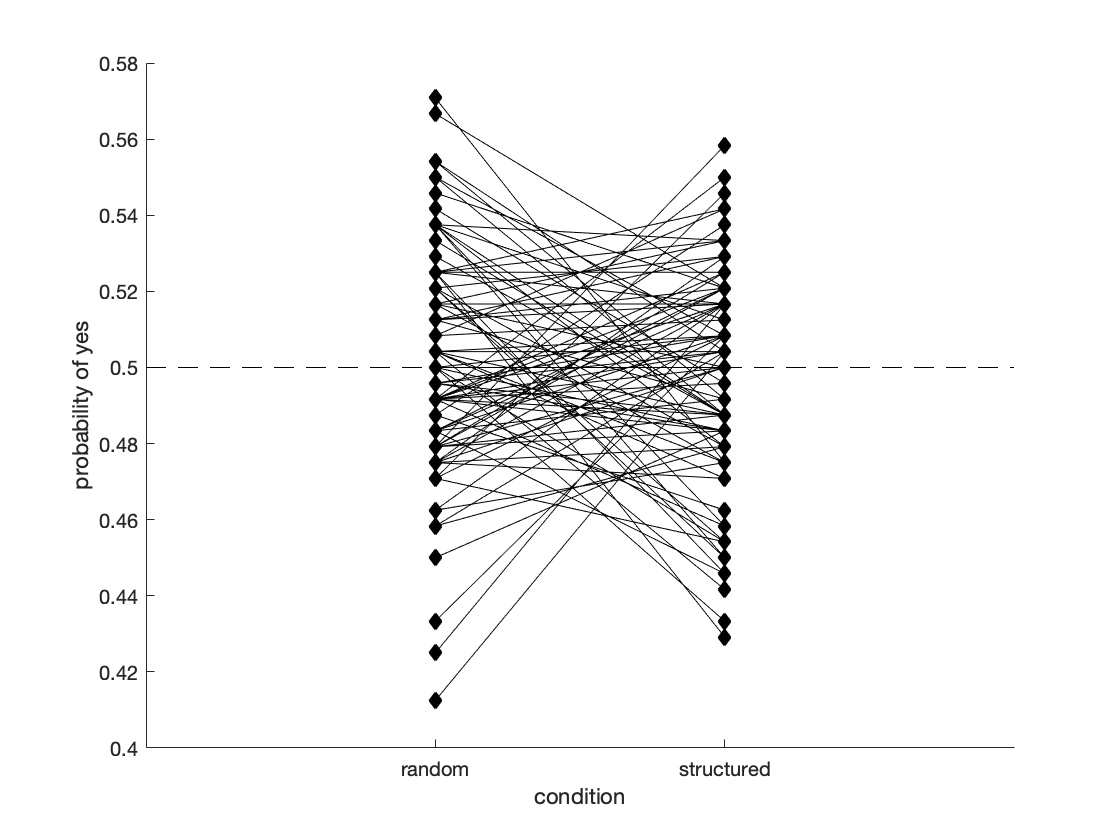

[rand_Pyes,struct_Pyes] = deal(nan(numel(subj_list),1));
for i_s = 1:numel(subj_list)
    subj = subj_list{i_s};
    rand_Pyes(i_s) = nanmean(data_struct(subj).RandomResp==1);
    struct_Pyes(i_s) = nanmean(data_struct(subj).StructResp==1);
end

figure; hold on;
plot([rand_Pyes';struct_Pyes'],'-dk','MarkerFaceColor','k');
ylabel('probability of yes');
xlim([0,3]); xlabel('condition');
plot([0,3],[0.5,0.5],'k--')
set(gca,'xtick',[1:2],'xticklabel',{'random','structured'});

%check significance
[h,p,ci,stats] = ttest(rand_Pyes-struct_Pyes);
[h_r,p_r,ci_r,stats_r] = ttest(rand_Pyes-0.5);
[h_s,p_s,ci_s,stats_s] = ttest(struct_Pyes-0.5);
sprintf(['Significance test: difference in response biases between the ' ...
    'structured and random conditions: t(%d)=%.2f, p=%.3f'],stats.df,stats.tstat,p)

ans = 'Significance test: difference in response biases between the structured and random conditions: t(99)=0.81, p=0.419'

## Visibility-response correlation

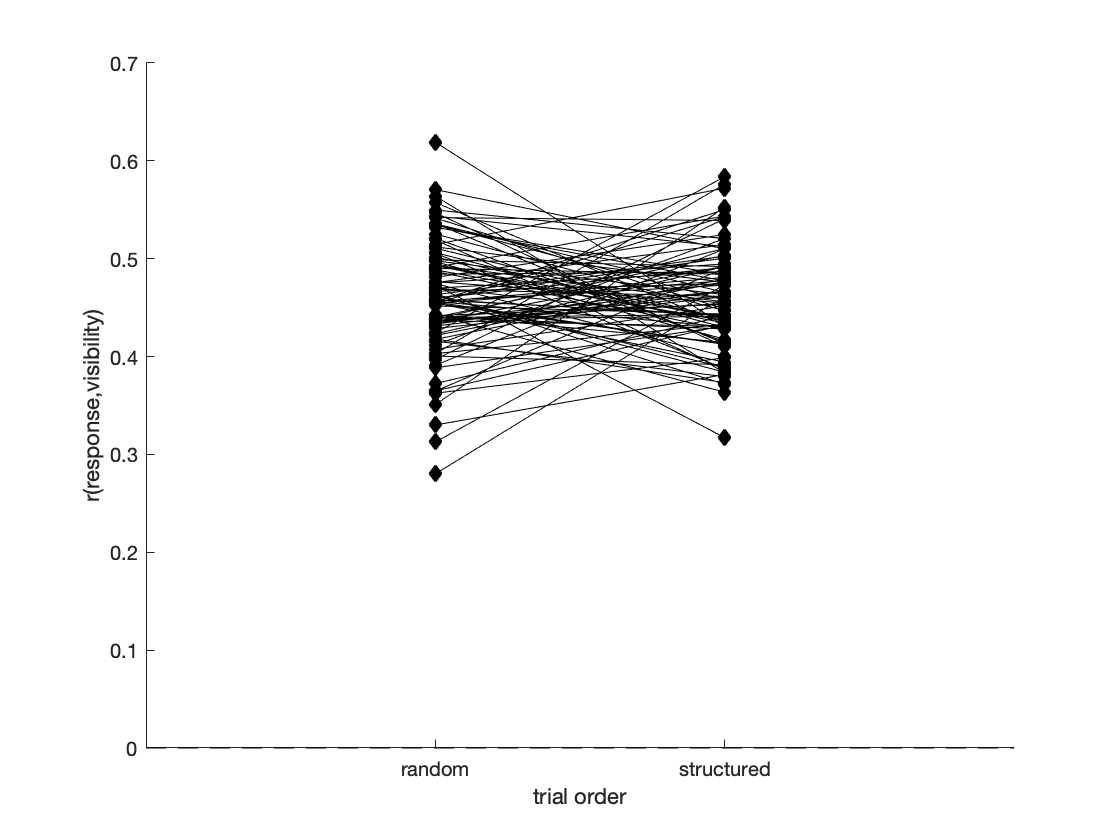

[rand_resp_corr,struct_resp_corr] = deal(nan(size(subj_list)));

for i_s = 1:numel(subj_list)
    
    subj = subj_list{i_s};
    
    rand_resp_corr(i_s) = nancorr(data_struct(subj).RandomVisibility, data_struct(subj).RandomResp);
    struct_resp_corr(i_s) = nancorr(data_struct(subj).StructVisibility, data_struct(subj).StructResp);
    
end

figure; hold on;
plot([rand_resp_corr;struct_resp_corr],'-dk','MarkerFaceColor','k');
ylabel('r(response,visibility)');
xlim([0,3]); xlabel('trial order');
plot([0,3],[0,0],'k--')
set(gca,'xtick',[1:2],'xticklabel',{'random','structured'});

%check significance
[h,p,ci,stats] = ttest(struct_resp_corr-rand_resp_corr);
sprintf(['Significance test: difference in visibility-response correlations between the ' ...
    'structured and random conditions: t(%d)=%.2f, p=%.3f'],stats.df,stats.tstat,p)

ans = 'Significance test: difference in visibility-response correlations between the structured and random conditions: t(99)=-0.46, p=0.644'

## Response Time

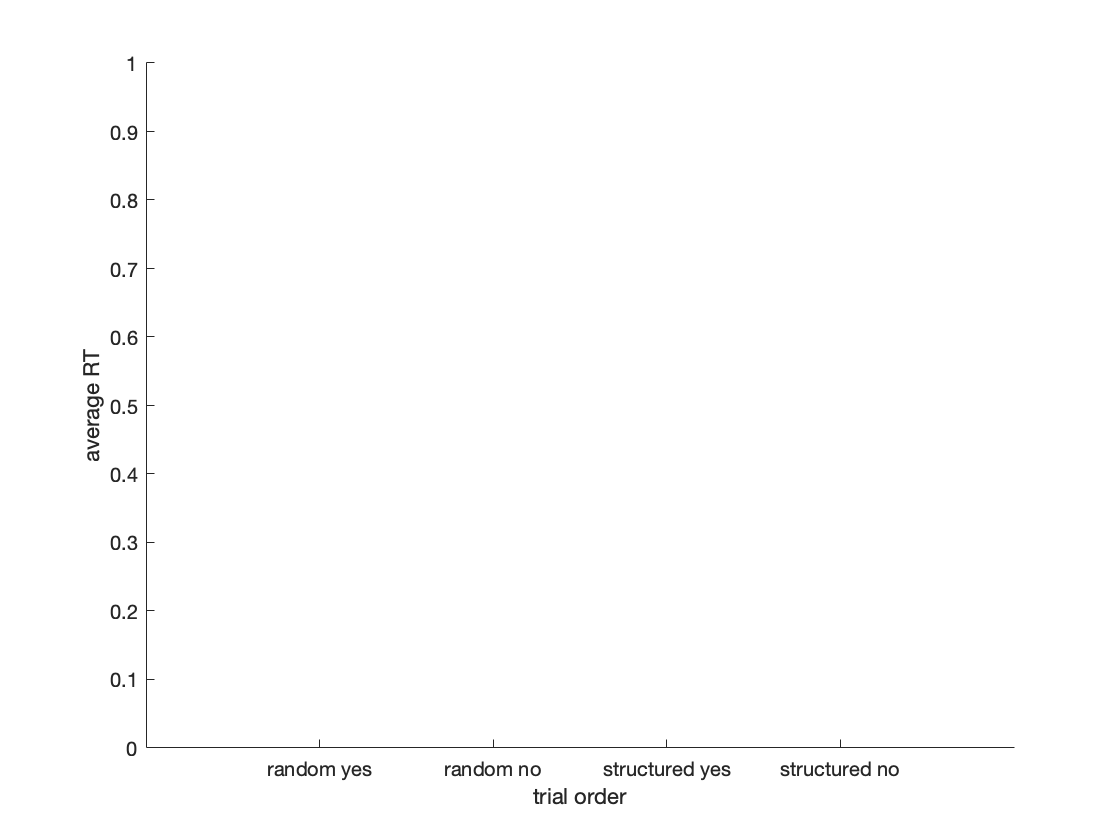

[rand_yes_RT,rand_no_RT,struct_yes_RT, struct_no_RT] = deal(nan(numel(subj_list),1));
for i_s = 1:numel(subj_list)
    subj = subj_list{i_s};
    rand_yes_RT(i_s) = nanmean(data_struct(subj).RandomRT(data_struct(subj).RandomResp==1));
    rand_no_RT(i_s) = nanmean(data_struct(subj).RandomRT(data_struct(subj).RandomResp==0));
    struct_yes_RT(i_s) = nanmean(data_struct(subj).StructRT(data_struct(subj).StructResp==1));
    struct_no_RT(i_s) = nanmean(data_struct(subj).StructRT(data_struct(subj).StructResp==0));
end

figure; hold on;
plot([rand_yes_RT';rand_no_RT';struct_yes_RT';struct_no_RT'],'-ok','MarkerFaceColor','k');
ylabel('average RT');
xlim([0,5]); xlabel('trial order');
set(gca,'xtick',[1:4],'xticklabel',{'random yes','random no', 'structured yes','structured no'});

## Visibility-RT correlation

% [rand_yes_VRTcorr,struct_yes_VRTcorr, rand_no_VRTcorr, struct_no_VRTcorr] = deal(nan(size(subj_list)));
% 
% for i_s = 1:numel(subj_list)
%     
%     subj = subj_list{i_s};
%     
%     demeaned_random_RT = data_struct(subj).RandomDemeanRT;
%     demeaned_struct_RT = data_struct(subj).StructDemeanRT;
%     demeaned_random_vis = data_struct(subj).RandomDemeanVisibility;
%     demeaned_struct_vis = data_struct(subj).StructDemeanVisibility;
%     
%     rand_yes_VRTcorr(i_s) = nancorr(demeaned_random_vis(data_struct(subj).RandomResp==1 & data_struct(subj).RandomCorrect==1),...
%         demeaned_random_RT(data_struct(subj).RandomResp==1 & data_struct(subj).RandomCorrect==1));
%     struct_yes_VRTcorr(i_s) = nancorr(demeaned_struct_vis(data_struct(subj).StructResp==1 & data_struct(subj).StructCorrect==1),...
%         demeaned_struct_RT(data_struct(subj).StructResp==1 & data_struct(subj).StructCorrect==1));
%     
%     rand_no_VRTcorr(i_s) = nancorr(demeaned_random_vis(data_struct(subj).RandomResp==0  & data_struct(subj).RandomCorrect==1),...
%         demeaned_random_RT(data_struct(subj).RandomResp==0  & data_struct(subj).RandomCorrect==1));
%     struct_no_VRTcorr(i_s) = nancorr(demeaned_struct_vis(data_struct(subj).StructResp==0  & data_struct(subj).StructCorrect==1),...
%         demeaned_struct_RT(data_struct(subj).StructResp==0 & data_struct(subj).StructCorrect==1));
%     
% end
% 
% figure; hold on;
% plot([rand_yes_VRTcorr;rand_no_VRTcorr;struct_yes_VRTcorr;struct_no_VRTcorr],'-ok','MarkerFaceColor','k');
% ylabel('r(log(RT),visibility)');
% xlim([0,5]); xlabel('trial order');
% set(gca,'xtick',[1:4],'xticklabel',{'random yes','random no', 'structured yes','structured no'});
% %check significance
% [h,p,ci,stats] = ttest(struct_no_VRTcorr-rand_no_VRTcorr);
% sprintf(['Significance test: difference in visibility-RT correlations in NO responses between the ' ...
%     'structured and random conditions: t(%d)=%.2f, p=%.3f'],stats.df,stats.tstat,p)

## Basic Counterfactual Model

[rand_yes_EVCcorr,struct_yes_EVCcorr, rand_no_EVCcorr, struct_no_EVCcorr] = deal(nan(size(subj_list)));

[rand_resp_EVcorr,struct_resp_EVcorr] = deal(nan(size(subj_list)));

[rand_yes_EVRTcorr,struct_yes_EVRTcorr, rand_no_EVRTcorr, struct_no_EVRTcorr] = deal(nan(size(subj_list)));

for i_s = 1:numel(subj_list)
    
    subj = subj_list{i_s};
    
    %setup variables
    
    struct_visibility = data_struct(subj).StructVisibility;
    struct_signal = data_struct(subj).StructSignal;
    struct_resp = data_struct(subj).StructResp;
    struct_expected_visibility = nan(size(struct_visibility)); %offset by 1 index to account for one-step expected values (i.e. first will be Nan)
    
    rand_visibility = data_struct(subj).RandomVisibility;
    rand_signal = data_struct(subj).RandomSignal;
    rand_resp = data_struct(subj).RandomResp;
    rand_expected_visibility = nan(size(rand_visibility)); %offset by 1 index to account for one-step expected values (i.e. first will be Nan)
    
    for i_v = 1:(numel(struct_visibility)-1)
        
        %structured condition
        
        st_vis = struct_visibility(i_v);
        st_pres = struct_signal(i_v);
        st_resp = struct_resp(i_v);
        st_currentExpVis = struct_expected_visibility(i_v);
        if i_v == 121 %2 blocks in vector and this is start of 2nd block
            struct_expected_visibility(i_v) = NaN;
        end
        if st_resp == 1 && st_pres == 1 %hit - change next expected visibility to current displayed visibility
            struct_expected_visibility(i_v+1) = st_vis;
        elseif (st_resp == 0 && st_pres == 1) || (st_resp == 0 && st_pres == 0) %miss or correct rejection - carry forward current expected visibility to next trial
            struct_expected_visibility(i_v+1) = st_currentExpVis;
        else %false alarm - set next expected visibility to a very low value
            struct_expected_visibility(i_v+1) = -5;
        end
        
        %random condition
        
        ra_vis = rand_visibility(i_v);
        ra_pres = rand_signal(i_v);
        ra_resp = rand_resp(i_v);
        ra_currentExpVis = rand_expected_visibility(i_v);
        if i_v == 121 %2 blocks in vector and this is start of 2nd block
            rand_expected_visibility(i_v) = NaN;
        end
        if ra_resp == 1 && ra_pres == 1 %hit - change next expected visibility to current displayed visibility
            rand_expected_visibility(i_v+1) = ra_vis;
        elseif (ra_resp == 0 && ra_pres == 1) || (ra_resp == 0 && ra_pres == 0) %miss or correct rejection - carry forward current expected visibility to next trial
            rand_expected_visibility(i_v+1) = ra_currentExpVis;
        else %false alarm - set next expected visibility to a very low value
            rand_expected_visibility(i_v+1) = -5;
        end
        
    end
    
    %demean the expected visibility
    
    demeaned_random_Evis = rand_expected_visibility - nanmean(rand_expected_visibility);
    demeaned_struct_Evis = struct_expected_visibility - nanmean(struct_expected_visibility);
    
    %calculate correlation between expected visibility and confidence
    
    demeaned_random_confidence = data_struct(subj).RandomDemeanConf;
    demeaned_struct_confidence = data_struct(subj).StructDemeanConf;
    
    struct_yes_EVCcorr(i_s) = nancorr(struct_expected_visibility(struct_resp==1 & data_struct(subj).StructCorrect==1),...
        demeaned_struct_confidence(struct_resp==1 & data_struct(subj).StructCorrect==1));
    struct_no_EVCcorr(i_s) = nancorr(struct_expected_visibility(struct_resp==0 & data_struct(subj).StructCorrect==1),...
        demeaned_struct_confidence(struct_resp==0 & data_struct(subj).StructCorrect==1));
    
    rand_yes_EVCcorr(i_s) = nancorr(rand_expected_visibility(rand_resp==1 & data_struct(subj).RandomCorrect==1),...
        demeaned_random_confidence(rand_resp==1 & data_struct(subj).RandomCorrect==1));
    rand_no_EVCcorr(i_s) = nancorr(rand_expected_visibility(rand_resp==0 & data_struct(subj).RandomCorrect==1),...
        demeaned_random_confidence(rand_resp==0 & data_struct(subj).RandomCorrect==1));
    
    %calculate correlation between expected visibility and response
    
    struct_resp_EVcorr(i_s) = nancorr(struct_expected_visibility, struct_resp);
    rand_resp_EVcorr(i_s) = nancorr(rand_expected_visibility, rand_resp);
    
    %calculate correlation between expected visibility and log RT
    
%     struct_yes_EVRTcorr(i_s) = nancorr(struct_expected_visibility(struct_resp==1 & data_struct(subj).StructCorrect==1),...
%         data_struct(subj).StructRT(struct_resp==1 & data_struct(subj).StructCorrect==1));
%     struct_no_EVRTcorr(i_s) = nancorr(struct_expected_visibility(struct_resp==0 & data_struct(subj).StructCorrect==1),...
%         data_struct(subj).StructRT(struct_resp==0 & data_struct(subj).StructCorrect==1));
%     
%     rand_yes_EVRTcorr(i_s) = nancorr(rand_expected_visibility(rand_resp==1 & data_struct(subj).RandomCorrect==1),...
%         data_struct(subj).RandomRT(rand_resp==1 & data_struct(subj).RandomCorrect==1));
%     rand_no_EVRTcorr(i_s) = nancorr(rand_expected_visibility(rand_resp==0 & data_struct(subj).RandomCorrect==1),...
%         data_struct(subj).RandomRT(rand_resp==0 & data_struct(subj).RandomCorrect==1));
%     
end


## E(Visibility)-confidence correlation

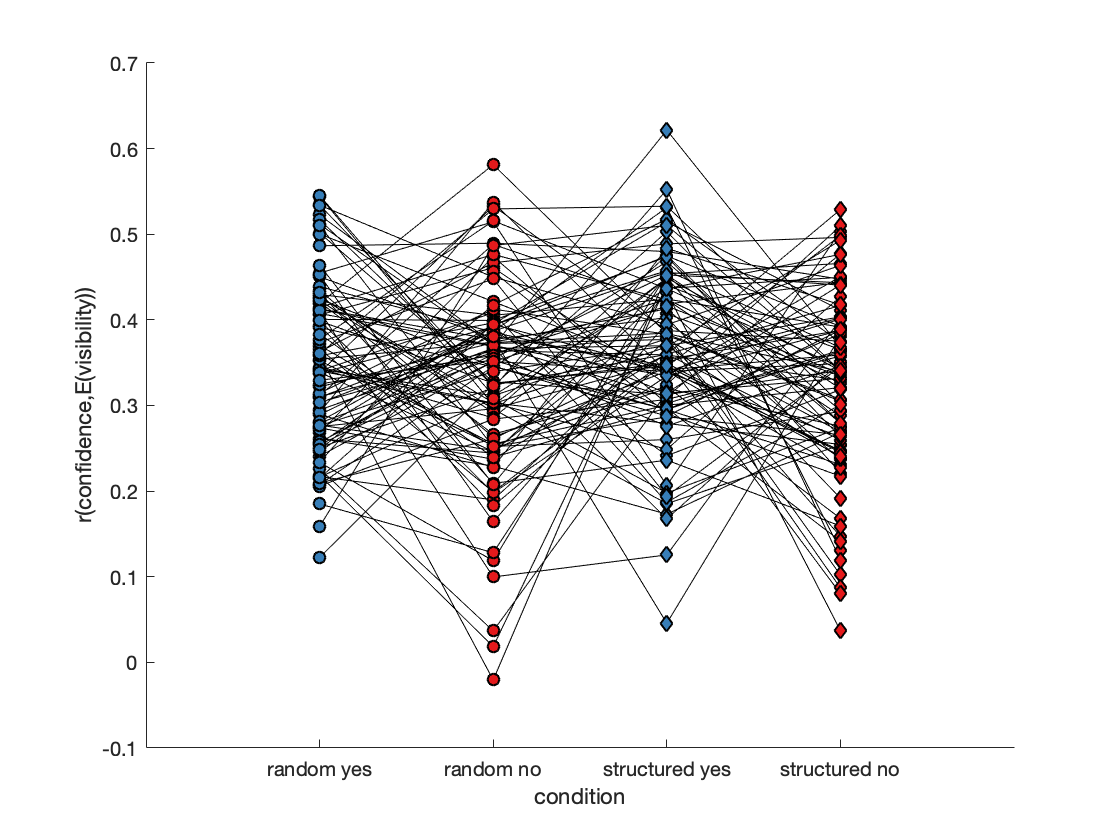

%plot correlation between expected visibility and confidence
%{
figure; hold on;
plot([rand_yes_EVCcorr;rand_no_EVCcorr;struct_yes_EVCcorr;struct_no_EVCcorr],'-ok','MarkerFaceColor','k');
ylabel('r(confidence,E(visibility))');
xlim([0,5]); xlabel('trial order');
set(gca,'xtick',[1:4],'xticklabel',{'random yes','random no', 'structured yes','structured no'});
%}
figure; hold on;
plot([rand_yes_EVCcorr;rand_no_EVCcorr;struct_yes_EVCcorr;struct_no_EVCcorr],'k');
scatter(ones(length(subj_list),1),rand_yes_EVCcorr,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(2*ones(length(subj_list),1),rand_no_EVCcorr,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
scatter(3*ones(length(subj_list),1),struct_yes_EVCcorr,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(4*ones(length(subj_list),1),struct_no_EVCcorr,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
ylabel('r(confidence,E(visibility))');
xlim([0,5]); xlabel('condition');
set(gca,'xtick',[1:4],'xticklabel',{'random yes','random no','structured yes','structured no'})
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/corrEVisConf','-dpng','-r600');

%significance test
[h,p,ci,stats] = ttest(struct_no_EVCcorr-rand_no_EVCcorr);
sprintf(['Significance test: difference in E(visibility)-confidence correlations between structured and ' ...
    'random conditions in NO responses: t(%d)=%.2f, p=%.3f'],stats.df,stats.tstat,p)

ans = 'Significance test: difference in E(visibility)-confidence correlations between structured and random conditions in NO responses: t(99)=-0.49, p=0.626'

[h,p,ci,stats] = ttest(0-struct_no_EVCcorr);
sprintf(['Significance test: E(visibility)-confidence correlations in the ' ...
    'structured condition in NO responses: t(%d)=%.2f, p=%.3f'],stats.df,stats.tstat,p)

ans = 'Significance test: E(visibility)-confidence correlations in the structured condition in NO responses: t(99)=-31.24, p=0.000'

[h,p,ci,stats] = ttest(0-rand_no_EVCcorr);
sprintf(['Significance test: E(visibility)-confidence correlations in the ' ...
    'random condition in NO responses: t(%d)=%.2f, p=%.3f'],stats.df,stats.tstat,p)

ans = 'Significance test: E(visibility)-confidence correlations in the random condition in NO responses: t(99)=-29.80, p=0.000'

## E(Visibility)-response correlation

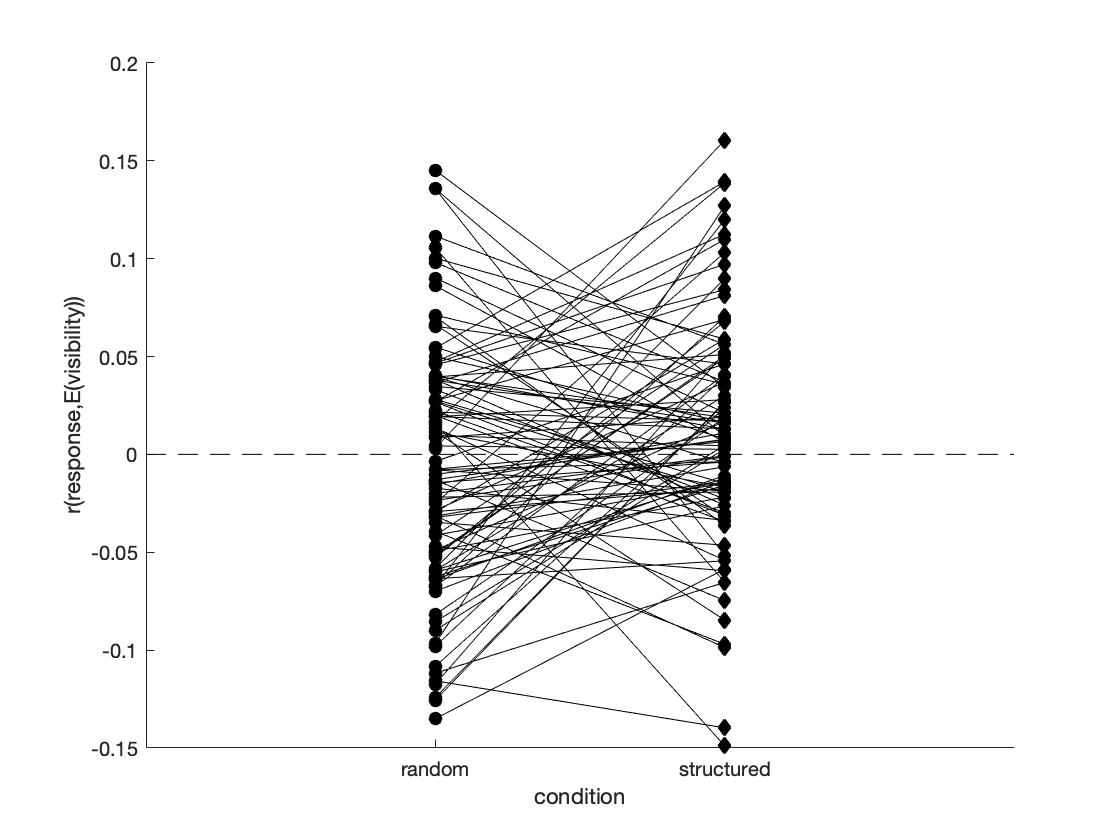

%plot correlation between expected visibility and response
%{
figure; hold on;
plot([rand_resp_EVcorr;struct_resp_EVcorr],'-dk','MarkerFaceColor','k');
ylabel('r(response,visibility)');
xlim([0,3]); xlabel('trial order');
plot([0,3],[0,0],'k--')
set(gca,'xtick',[1:2],'xticklabel',{'random','structured'});
%}
figure; hold on;
plot([rand_resp_EVcorr;struct_resp_EVcorr],'-k');
scatter(ones(length(subj_list),1),rand_resp_EVcorr,[],'o','MarkerEdgeColor','k','MarkerFaceColor','k','LineWidth',1);
scatter(2*ones(length(subj_list),1),struct_resp_EVcorr,[],'d','MarkerEdgeColor','k','MarkerFaceColor','k','LineWidth',1);
ylabel('r(response,E(visibility))');
xlim([0,3]); xlabel('condition');
plot([0,3],[0,0],'k--')
set(gca,'xtick',[1:2],'xticklabel',{'random','structured'})
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/corrEVisResp','-dpng','-r600');

%check significance
[h,p,ci,stats] = ttest(struct_resp_EVcorr-rand_resp_EVcorr);
sprintf(['Significance test: difference in E(visibility)-response correlations between the ' ...
    'structured and random conditions: t(%d)=%.2f, p=%.3f'],stats.df,stats.tstat,p)

ans = 'Significance test: difference in E(visibility)-response correlations between the structured and random conditions: t(99)=2.10, p=0.038'

## E(Visibility)-RT correlation

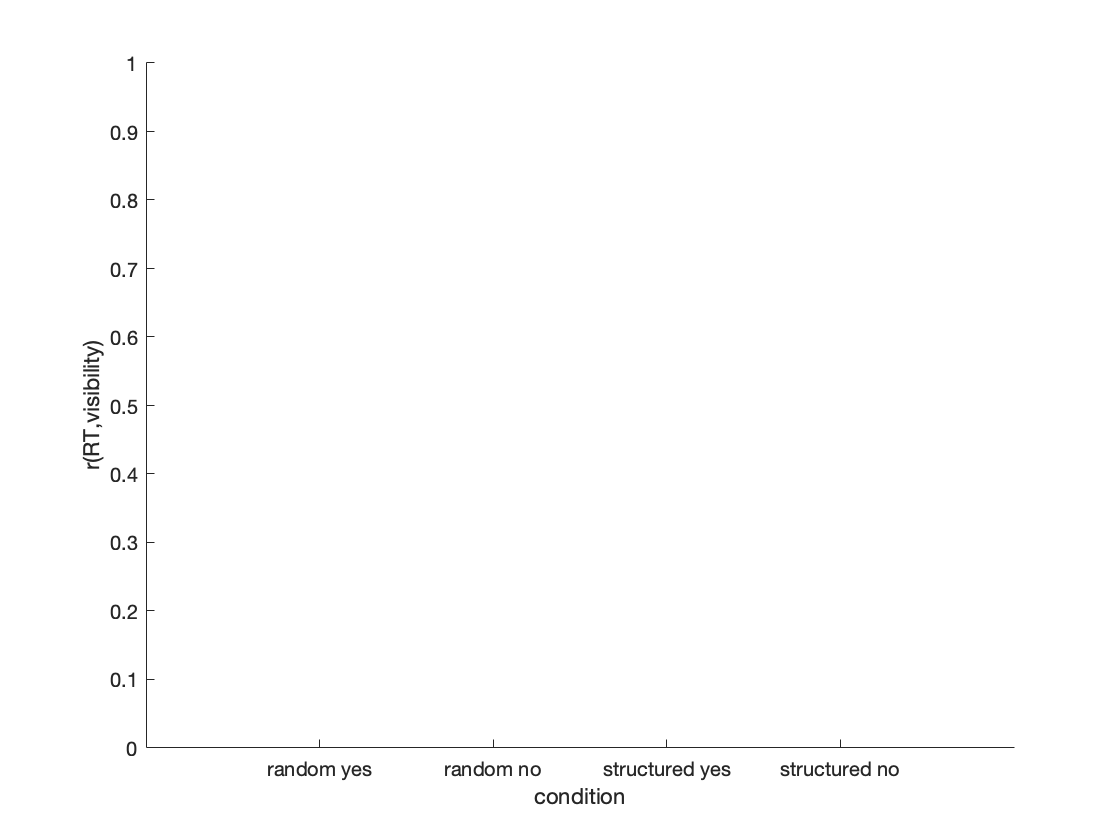

%plot correlation between expected visibility and RT
figure; hold on;
plot([rand_yes_EVRTcorr;rand_no_EVRTcorr;struct_yes_EVRTcorr;struct_no_EVRTcorr],'-ok','MarkerFaceColor','k');
ylabel('r(RT,visibility)');
xlim([0,5]); xlabel('condition');
set(gca,'xtick',[1:4],'xticklabel',{'random yes','random no', 'structured yes','structured no'});

%check significance
[h,p,ci,stats] = ttest(struct_no_EVRTcorr-rand_no_EVRTcorr);
sprintf(['Significance test: difference in E(visibility)-RT correlations in NO responses between the ' ...
    'structured and random conditions: t(%d)=%.2f, p=%.3f'],stats.df,stats.tstat,p)

ans = 'Significance test: difference in E(visibility)-RT correlations in NO responses between the structured and random conditions: t(0)=NaN, p=NaN'

## Serial correlations

% Struct_Coeffs = [];
% Rand_Coeffs = [];
% 
% Struct_corr = [];
% Rand_corr = [];
% 
% isRandFirstVec = [];
% 
% for s=1:length(subj_list) %run over subjects
%     
%     subject = data_struct(subj_list{s});
%     
%     StructRespMat = [];
%     RandRespMat = [];
%     
%     StructSigMat = [];
%     RandSigMat = [];
%     
%     isRandFirstVec =[isRandFirstVec; 0]; %random is second in this version %[isRandFirstVec; subject.isRandomFirst];
%     
%     StructRespBlock1 = subject.StructResp(1:119); %responses for structured
%     StructRespBlock2 = subject.StructResp(121:239); %responses for structured
%     RandRespBlock1 = subject.RandomResp(1:119); %responses for random
%     RandRespBlock2 = subject.RandomResp(121:239); %responses for random
%     
%     StructSigBlock1 = subject.StructSignal(2:120); %signal for structured
%     StructSigBlock2 = subject.StructSignal(122:240); %signal for structured
%     RandSigBlock1 = subject.RandomSignal(2:120); %signal for random
%     RandSigBlock2 = subject.RandomSignal(122:240); %signal for random
%     
%     StructVisBlock1 = nanzscore(subject.StructDemeanVisibility(2:120));
%     StructVisBlock1(subject.StructSignal(2:120)==0)=0;
%     StructVisBlock2 = nanzscore(subject.StructDemeanVisibility(122:240));
%     StructVisBlock2(subject.StructSignal(122:240)==0)=0;
%     RandVisBlock1 = nanzscore(subject.RandomDemeanVisibility(2:120));
%     RandVisBlock1(subject.StructSignal(2:120)==0)=0;
%     RandVisBlock2 = nanzscore(subject.RandomDemeanVisibility(122:240));
%     RandVisBlock2(subject.StructSignal(122:240)==0)=0;
%     
%     StructExpVisBlock1 = nanzscore(demeaned_struct_Evis(2:120));
%     StructExpVisBlock2 = nanzscore(demeaned_struct_Evis(122:240));
%     RandExpVisBlock1 = nanzscore(demeaned_random_Evis(2:120));
%     RandExpVisBlock2 = nanzscore(demeaned_random_Evis(122:240));
%     
%     StructDesignMatrix = [[StructRespBlock1;StructRespBlock2],[StructSigBlock1;StructSigBlock2],...
%         [StructVisBlock1;StructVisBlock2],[StructExpVisBlock1;StructExpVisBlock2]];
%     RandDesignMatrix = [[RandRespBlock1;RandRespBlock2],[RandSigBlock1;RandSigBlock2],...
%         [RandVisBlock1;RandVisBlock2],[RandExpVisBlock1;RandExpVisBlock2]];
%     
%     toPredictStruct = [subject.StructResp(2:120);subject.StructResp(122:240)]; % what I want to predict is the last response at t
%     toPredictStruct(toPredictStruct==0)=2; %the second category is used as reference by mnrfit
%     Struct_B = mnrfit(StructDesignMatrix, toPredictStruct); %fit a logistic regression model
%     
%     toPredictRand = [subject.RandomResp(2:120);subject.RandomResp(122:240)];
%     toPredictRand(toPredictRand==0)=2; %the second category is used as reference by mnrfit
%     Rand_B = mnrfit(RandDesignMatrix, toPredictRand); %fit a logistic regression model
%     
%     Struct_Coeffs = [Struct_Coeffs Struct_B(2:length(Struct_B))]; % add only the slope betas and not the bias
%     Rand_Coeffs = [Rand_Coeffs Rand_B(2:length(Struct_B))]; % add only the slope betas and not the bias
%     %{
%     Struct_corr = cat(3, Struct_corr, corr(StructDesignMatrix(~any(isnan(StructDesignMatrix),2),:))); %compute correlations
%     Rand_corr = cat(3, Rand_corr, corr(RandDesignMatrix(~any(isnan(RandDesignMatrix),2),:)));  %compute correlations
%     %}
% end
%{
% Struct_corr_vec = squeeze(Struct_corr(5:-1:1,6,:))';
% Rand_corr_vec = squeeze(Rand_corr(5:-1:1,6,:))';
% figure
% hold on
% mseb(1:5, [mean(Struct_corr_vec);mean(Rand_corr_vec)] ,...
%     [std(Struct_corr_vec); std(Rand_corr_vec)]/sqrt(length(subj_list))*2, lineProps);
% legend('structured','random')
% plot([1,5],[0,0],'--k');
% xlabel('lag');
% ylabel('correlation')
% %}
% 
% %extract useful data (visibility, expected visibility weights)
% Struct_CoeffsT = Struct_Coeffs';
% Struct_VisEVisCoeffs = Struct_CoeffsT(:,3:4);
% Struct_EVisCoeffs = Struct_CoeffsT(:,4);
% Rand_CoeffsT = Rand_Coeffs';
% Rand_VisEVisCoeffs = Rand_CoeffsT(:,3:4);
% Rand_EVisCoeffs = Rand_CoeffsT(:,4);
% 
% %plot figure for all predictors
% figure;
% subplot(1,2,1);
% hold on;
% mseb(1:4, [mean(Struct_CoeffsT);mean(Rand_CoeffsT)],...
%     [std(Struct_CoeffsT); std(Rand_CoeffsT)]/sqrt(length(subj_list)), lineProps);
% legend('structured','random')
% plot([1,4],[0,0],'--k');
% set(gca,'xtick',[1:4],'xticklabel',{'response', 'signal', 'visibility', 'expectedVisibility'})
% xlabel('predictor');
% ylabel('weight')
% 
% %subplot of figure with just vis and EVis as predictors
% subplot(1,2,2);
% hold on;
% mseb(1:2, [mean(Struct_VisEVisCoeffs);mean(Rand_VisEVisCoeffs)],...
%     [std(Struct_VisEVisCoeffs); std(Rand_VisEVisCoeffs)]/sqrt(length(subj_list)), lineProps);
% legend('structured','random')
% plot([1,2],[0,0],'--k');
% set(gca,'xtick',[1:4],'xticklabel',{'visibility', 'expectedVisibility'})
% xlabel('predictor');
% ylabel('weight')
% %plot beta values of each participant for EVis as a predictor for responses in logistic regression
% %'-ok','MarkerFaceColor',
% figure; hold on;
% plot([Struct_EVisCoeffs';Rand_EVisCoeffs'],'k');
% scatter(ones(length(subj_list)-sum(isRandFirstVec),1),(Struct_EVisCoeffs(isRandFirstVec==0))',[],'d','MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
% scatter(ones(sum(isRandFirstVec),1),(Struct_EVisCoeffs(isRandFirstVec==1))',[],'d','MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
% scatter(2*ones(length(subj_list)-sum(isRandFirstVec),1),(Rand_EVisCoeffs(isRandFirstVec==0))',[],'MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
% scatter(2*ones(sum(isRandFirstVec),1),(Rand_EVisCoeffs(isRandFirstVec==1))',[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
% %scatter(2*ones(length(subj_list),1),rand_no_VCcorr,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
% ylabel('beta coefficients for expectedVisibility)');
% xlim([0,3]); xlabel('condition');
% set(gca,'xtick',[1:2],'xticklabel',{'structured','random'});
% 
% 
% 
% % check overall difference in dependency temporal window:
% Struct_window = [];
% Rand_window = [];
% Struct_height = [];
% Rand_height = [];
% for s = 1:length(subj_list)
%     Struct_window(s) = find([Struct_Coeffs(:,s); 0]<=0,1);
%     Rand_window(s) = find([Rand_Coeffs(:,s); 0]<=0,1);
%     Struct_height(s) = mean(Struct_Coeffs(1:Struct_window(s)-1,s));
%     Rand_height(s) = mean(Rand_Coeffs(1:Struct_window(s)-1,s));
%     
% end
% 
% %{
% %3.1 Alternating and sustained effects of previous trials
% 
% alternating_regressor = [-1 1 -1 1 -1 1 -1];
% sustained_regressor = 3:-1:-3;
% predictors = [ones(7,1), alternating_regressor', sustained_regressor'];
% trends_Struct = [];
% trends_Rand = [];
% 
% for i_s = 1:length(subj_list)
%     trends_Struct(:, i_s) = regress(Struct_Coeffs(:,i_s), predictors);
%     trends_Rand(:, i_s) = regress(Rand_Coeffs(:,i_s), predictors);
% end
%}